%{
x = [1, 2, 3, 4, 5]; % Independent variable
y = flip([3.6, 7.2, 14.4, 28.8, 57.6]); % Corresponding dependent variable

% Define the model function
model = @(A, x) A * exp(x);

% Define the error function (to be minimized)
error_function = @(A) sum((model(A, x) - y).^2);

% Initial guess for the parameter A
initial_guess_A = 1;

% Perform nonlinear least squares fitting using fminsearch
optimal_A = fminsearch(error_function, initial_guess_A);

% Output the optimal parameter
disp(['Optimal A:', num2str(optimal_A)]);

% Plot the data and the fitted curve
x_values = linspace(min(x), max(x), 100);
y_values = model(optimal_A, x_values);

figure;
plot(x, y, 'bo', 'MarkerSize', 10); % Data points
hold on;
plot(x_values, y_values, 'r-', 'LineWidth', 2); % Fitted curve
xlabel('x');
ylabel('y');
title('Exponential Regression: A * exp(x)');
legend('Data', 'Fitted Curve');
grid on;
%}

% Define your data
x = [4.5 10 9 5 5 9.5]%[1, 2, 3, 4, 5]; % Independent variable

x =     4.5000   10.0000    9.0000    5.0000    5.0000    9.5000


y = [2.387 3.5 2.5 3 3.4 4.5]./x %[2, 8, 18, 32, 50]; % Corresponding dependent variable

y =     0.5304    0.3500    0.2778    0.6000    0.6800    0.4737



% Define the model function
model = @(A, c, x) A * x.^c;

% Define the error function (to be minimized)
error_function = @(params) sum((model(params(1), params(2), x) - y).^2);

% Initial guess for the parameters A and c
initial_guess = [1, 1]; % Change these values according to your data

% Perform nonlinear least squares fitting using fminsearch
optimal_params = fminsearch(error_function, initial_guess);

% Output the optimal parameters
optimal_A = optimal_params(1);
optimal_c = optimal_params(2);
disp(['Optimal A:', num2str(optimal_A)]);

Optimal A:1.7086


disp(['Optimal c:', num2str(optimal_c)]);

Optimal c:-0.67155


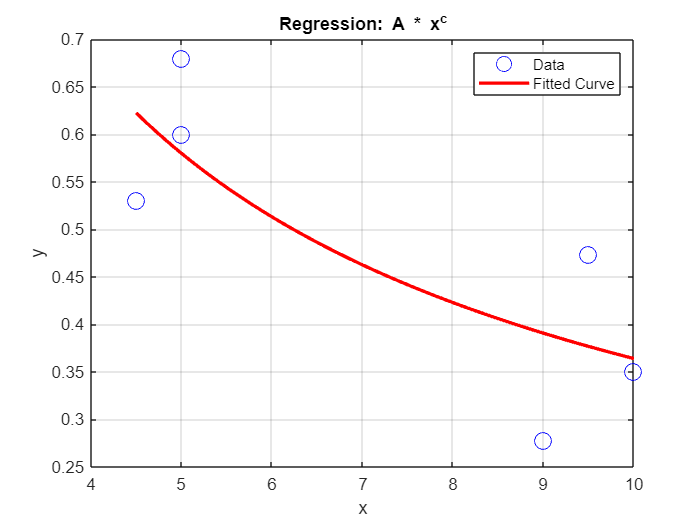


% Plot the data and the fitted curve
x_values = linspace(min(x), max(x), 100);
y_values = model(optimal_A, optimal_c, x_values);

figure;
plot(x, y, 'bo', 'MarkerSize', 10); % Data points
hold on;
plot(x_values, y_values, 'r-', 'LineWidth', 2); % Fitted curve
xlabel('x');
ylabel('y');
title('Regression: A * x^c');
legend('Data', 'Fitted Curve');
grid on;
saveas(gcf,'Regression.png')


A1 = optimal_A

A1 = 1.7086

c1 = optimal_c

c1 = -0.6716

x = [4.5
10
9
5
5
%7.5
%7
%7
%5.7
9.5]

x =     4.5000
   10.0000
    9.0000
    5.0000
    5.0000
    9.5000


y = [0.604
2.4
2.8
0.595+0.595
0.604
%2.3
%1.2
%0.8
%0.6
1.5]./x %[1, 2, 3, 4, 5]; % Independent variable

y =     0.1342
    0.2400
    0.3111
    0.2380
    0.1208
    0.1579


%y = [2.387,3.5,3,3.6, 3.3]./x %[2, 8, 18, 32, 50]; % Corresponding dependent variable

% Define the model function
model = @(A, c, x) A * x.^c;

% Define the error function (to be minimized)
error_function = @(params) sum((model(params(1), params(2), x) - y).^2);

% Initial guess for the parameters A and c
initial_guess = [1, 1]; % Change these values according to your data

% Perform nonlinear least squares fitting using fminsearch
optimal_params = fminsearch(error_function, initial_guess);

% Output the optimal parameters
optimal_A = optimal_params(1);
optimal_c = optimal_params(2);
disp(['Optimal A:', num2str(optimal_A)]);

Optimal A:0.075227


disp(['Optimal c:', num2str(optimal_c)]);

Optimal c:0.50474


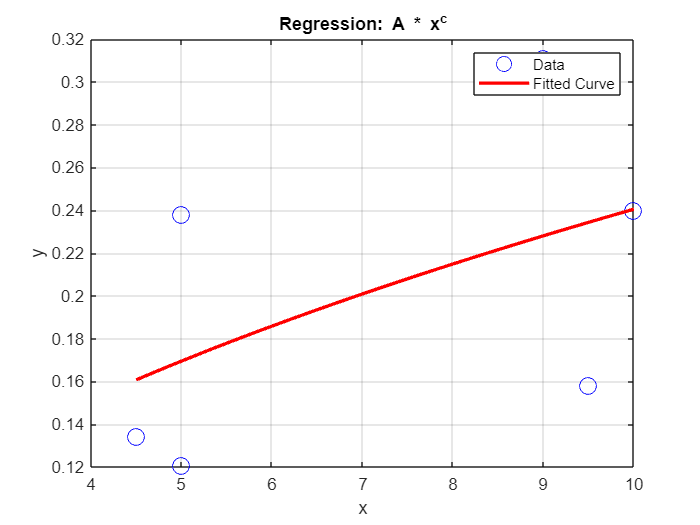


% Plot the data and the fitted curve
x_values = linspace(min(x), max(x), 100);
y_values = model(optimal_A, optimal_c, x_values);

figure;
plot(x, y, 'bo', 'MarkerSize', 10); % Data points
hold on;
plot(x_values, y_values, 'r-', 'LineWidth', 2); % Fitted curve
xlabel('x');
ylabel('y');
title('Regression: A * x^c');
legend('Data', 'Fitted Curve');
grid on;

W_0_initial = 4*1.4

W_0_initial = 5.6000

W_payload = 1.4

W_payload = 1.4000

W_battery_w0 = 0.2540 %@(x) optimal_A*x^(optimal_c)%0.2 %Creating variable for battery weight

W_battery_w0 = 0.2540

W_empty_w0 = @(x) A1*x^(c1) % creating variable for empty weight

W_empty_w0 = function_handle with value:
    @(x)A1*x^(c1)


W_0 = W_0_initial %setting up initial weight

W_0 = 5.6000

W_empty_w0(W_0) 

ans = 0.5373

for i = 1:1:1000
    W_0_new = W_payload/(1 - (W_battery_w0) - (W_empty_w0(W_0))); %estimate new W_0
    W_0 = 0.5*(W_0 + W_0_new); %averaging W_0 from previous and new iteration
end
W_0

W_0 = 6.0030